# Adaptive control for systems with dead time

## Adaptive control strategy: Self tuning controller

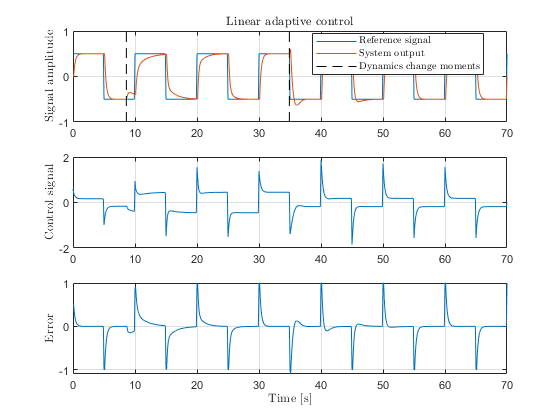

sqareWaveGen = @(t, T)((t - T*floor(t/T)) < T/2);
Kf = 3;
Tf = 1;
T0 = Tf/4;
Tm = 0.1;
Te = 0.1;
N = Tm/Te;
T = 100*Te;
t = 0:Te:7*T;
u = sqareWaveGen(t, T) - 0.5;

%Hf = tf(Kf, [Tf 1], 'iodelay', Tm);
Hfd = tf(Kf*(1 - exp(-Te/Tf)), [1 -exp(-Te/Tf)], Te, 'iodelay', 1);
Af = exp(-Te/Tf);
Ac = exp(-Te/T0);
Kc = (1 - Ac)/(Kf*(1 - Af));
%Hc = tf(Kc*[1 -Af 0], [1 -Ac Ac - 1], Te);

[num, den] = tfdata(Hfd, 'v');
system = DiscreteModelZoh(num, den(2:end));
[num, den] = getDiscreteController(den(2), num(2), T0, Te);
controller = DiscreteModel(num, den(2:end));

output = zeros(length(t), 1);
command = zeros(length(t), 1);
error = zeros(length(t), 1);
error(1) = u(1);
m = floor(length(u)/2);
aux = m;

% system polynomial orders
na = 1;
nb = 0;
nd = 2;
windowSize = 180; % observation vector and measurements size
wIdx = 1;
window = zeros(na + nb + 1, 1); 
inputBuffer = zeros(nd, 1);
outputBuffer = zeros(1, 1);
wY = zeros(windowSize, 1); % measurements
phi = zeros(nb + na + 1, windowSize); % observation vector

% Optimizer utility functions
evalGradient = @(theta, phi, y)(-2*sum((y - theta'*phi).*phi, 2));
evalHessian = @(phi)(2*phi*phi');
evalCost = @(theta, phi, y)(sum((y - theta'*phi).^2));
alpha = 1; % optimizer step
beta = 1.1; % bactracking step increment
alphaUpperThreshold = 10000; % step upper boundary
alphaBottomTreshold = 0.00000001; % step bottom boundary

% paramters to optimize
[num, den] = tfdata(Hfd, 'v');
theta = [num(2:end)'; den(2:end)'];
theta = [theta theta];

% non-zero intial conditions avoidance
timeUnitsToWait = max(nb + nd, na) + 1;
timeUnitsWaited = 0;
isReady = false;
f = 1;
changeTime = zeros(2, 1);
for i = 1:length(u)-1
    [controller, command(i)] = forward(controller, error(i));
    [system, output(i), nextRes] = forward(system, command(i));
    error(i + 1) = u(i + 1) - nextRes;
    
    if i == floor(length(u)/8) || i == floor(length(u)/2) 
        Kfm = normrnd(Kf, 1.5);
        %Kf = Kf + 10;
        Tfm = normrnd(Tf, 0.5);
        Hfd = tf(Kfm*(1 - exp(-Te/Tfm)), [1 -exp(-Te/Tfm)], Te, 'iodelay', 1);
        [num, den] = tfdata(Hfd, 'v');
        system.num = num;
        system.den = den(2:end);
        changeTime(f) = t(i);
        f = f + 1;
        m = m + aux;
    end
    
    if nd >= 1
        window(1) = inputBuffer(1);
    else
        window(1) = command(i);
    end
    for j = 2:nb+1
        if wIdx - 1 >= 1
            window(j) = phi(j - 1, wIdx - 1);
        end
    end
    if nd > 1 
        inputBuffer(1:end-1) = inputBuffer(2:end);
        inputBuffer(end) = command(i);
    else
        inputBuffer = command(i);
    end
    
    window(nb + 2) = -outputBuffer;
    for k = nb+3:nb+1+na
        if wIdx - 1 >= 1
            window(k) = phi(k - 1, wIdx - 1);
        end
    end
    outputBuffer = output(i);
    
    if wIdx <= windowSize
        phi(:, wIdx) = window;
        wY(wIdx) = output(i);
        idx = wIdx;
        wIdx = wIdx + 1;
    else
        phi = [phi(:, 2:end) window];
        wY = [wY(2:end); output(i)];
    end
    
    if isReady == false && timeUnitsWaited >= timeUnitsToWait
        isReady = true;
        phi = [phi(:, timeUnitsToWait+1:end) zeros(nb + na + 1, timeUnitsToWait)];
        wY = [wY(timeUnitsToWait+1:end); zeros(timeUnitsToWait, 1)];
        wIdx = 2;
        idx = 1; 
    end
    
    if isReady == false
        timeUnitsWaited = timeUnitsWaited + 1;
    else
         % AAP
        gradient = evalGradient(theta(:, 1), phi(:, 1:idx), wY(1:idx)');
        if norm(gradient) ~= 0 
            gradient = gradient/norm(gradient);
            if rank(phi(:, 1:idx)) == na + nb + 1
                hessian = evalHessian(phi(:, 1:idx));
                hessian = hessian/norm(hessian);
                optimizerDirection = hessian\gradient;
            else
                optimizerDirection = gradient;
            end
           
            theta(:, 2) = theta(:, 1) - optimizerDirection*alpha;
            cost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
            newAlpha = beta*alpha;
            theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
            newCost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
            
            if newCost < cost
                while newCost < cost && newAlpha < alphaUpperThreshold
                    cost = newCost;
                    newAlpha = beta*newAlpha;
                    theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
                    newCost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
                end
                newAlpha = newAlpha/beta;
                theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
            else
                newAlpha = alpha/beta;
                theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
                newCost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
                
                if newCost < cost 
                    while newCost < cost && newAlpha > alphaBottomTreshold
                        cost = newCost;
                        newAlpha = newAlpha/beta;
                        theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
                        newCost = evalCost(theta(:, 2), phi(:, 1:idx), wY(1:idx)');
                    end
                    newAlpha = newAlpha*beta;
                    theta(:, 2) = theta(:, 1) - optimizerDirection*newAlpha;
                else
                    theta(:, 2) = theta(:, 1) - optimizerDirection*alpha;
                end
            end
            theta(:, 1) = theta(:, 2);
        end
        if mod(i, 10) == 0
            [num, den] = getDiscreteController(theta(2, 2), theta(1, 2), T0, Te);
            controller.num = num;
            controller.den = den(2:end);
        end
    end
end

figure,
subplot(3, 1, 1);
plot(t, u);
hold on;
plot(t, output); grid;
xline = -1:0.1:1;
yline = changeTime.*ones(length(xline), 2)';
plot(yline, xline, '--', "Color", [0 0 0]);
title("Linear adaptive control", "Interpreter", "Latex");
ylabel("Signal amplitude", "Interpreter", "latex");
legend("Reference signal", "System output", "Dynamics change moments", ...
    "Interpreter", "Latex", "Location","best");

subplot(3, 1, 2);
plot(t, command); grid;
ylabel("Control signal", "Interpreter", "latex");

subplot(3, 1, 3);
plot(t, error); grid;
xlabel("Time [s]", "Interpreter", "latex");
ylabel("Error", "Interpreter", "latex");

function [num, den] = getDiscreteController(a1, b0, T0, Te)
    Tf = -Te/log(-a1);
    Kf = b0/(1 + a1);
    Af = exp(-Te/Tf);
    Ac = exp(-Te/T0);
    Kc = (1 - Ac)/(Kf*(1 - Af));
    num = Kc*[1 -Af 0];
    den = [1 -Ac Ac - 1];
end